## Derivative Rules

The basic limit definition of the derivative can be slow and awkward to apply. For most standard functions, it is easier to prove a few rules for simple functions and then compute complicated derivatives by breaking the functions down into simple pieces that fit the known rules.

 This live script is intended to be used with the code hidden. Select the `VIEW` tab and switch to Hide Code.

 If you find the MATLAB coding in this script to be challenging, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## Power Rule

clear
syms x h
n = 0

n = 0

f(x) = x^n;
fh = f(x+h);
oldPrefs = sympref();
sympref('PolynomialDisplayStyle', 'descend');
sympref('FloatingPointOutput',false);

Calculate fxph = $f(x+h)$:

fxph(x,h) = taylor(f(x+h),x, "ExpansionPoint",0, "Order", 11)

$$fxph(x, h) = 1$$

Calculate the difference quotient DQ = $\frac{f(x+h)-f(x)}{h}$:

DQ(x,h) = (fxph - f(x))/h

$$DQ(x, h) = 0$$

Simplify the difference quotient:

DQ(x,h) = simplify(DQ(x,h))

$$DQ(x, h) = 0$$

Compute the limit of the difference quotient as $h \to 0$:

dfdx = $\frac{df}{dx} = \lim_{h\to 0} \frac{f(x+h)-f(x)}{h}$

dfdx(x) = DQ(x,0)

$$dfdx(x) = 0$$

  **Try **Change the value of $n$ and see if you can find a pattern to the result. For a positive, integer $n$, can you write down a rule for the derivative?

If $f(x) = x^n$, then $\frac{df}{dx}$ = ? 

syms x n
dfdx = n*x^(n);
checkPwrRule(dfdx);

No, that isn't correct. Please try again.


### Extending the Power Rule

What happens if $n$ is not a positive integer? If $n=0$ this is quite doable by hand, but what happens with other values? Does your rule still work?

syms x h
n = -3

n = -3

order = 5

order = 5

f(x) = x^n

$$f(x) = \frac{1}{x^{3}}$$

fxph(x,h) = f(x+h);
DQ(x,h) = (simplify(taylor(fxph,h, 'Order', order)-f(x))/h)

$$DQ(x, h) = \frac{-3\,x^{3}+6\,h\,x^{2}-10\,h^{2}\,x+15\,h^{3}}{x^{7}}$$

dfdx(x) = DQ(x,0)

$$dfdx(x) = -\frac{3}{x^{4}}$$

  **Pro-tip**. The method used to approximate the difference quotient here is called a [Taylor Series](https://www.mathworks.com/help/symbolic/sym.taylor.html#busozb7-8). This is an extremely useful method you are likely to see again. 

 **Practice.**

Compute the derivative of the following expressions:

- 
$$x^2$$


- 
$$x^{-2$$


- 
$$x^{1/2$$


- 
$$3$$


pwrRuleChecked = true;
if pwrRuleChecked
    syms x;
    disp("1. ")
    ans1 = 2*x
    disp("2. ")
    ans2 = -2*x
    disp("3. ")
    ans3 = 1/2*x^(-1/2)
    disp("4. ")
    ans4 = 0
    disp("Note: This can be thought of as a power rule in terms of x^0, but it is sometimes called the Constant Rule.")
    disp("      The derivative of any constant is zero!")
end

1. 


$$ans1 = 2\,x$$

2. 


$$ans2 = -2\,x$$

3. 


$$ans3 = \frac{1}{2\,\sqrt{x}}$$

4. 


ans4 = 0

Note: This can be thought of as a power rule in terms of x^0, but it is sometimes called the Constant Rule.


      The derivative of any constant is zero!


Take the derivative with respect to: 


$$z$$

 of the function f = 


$$3\,z^{9}$$

When simplified, my answer is: 


$$myAnswer = 27\,z^{6}$$

My answer is incorrect. The correct answer is:


$$correctAnswer = 27\,z^{8}$$

Please try again with a new problem.


## Linearity Rules

Remember that we called the derivative an *operator*. In fact, it is a **linear** operator, which means that it satisfies the following conditions for any differentiable functions $f(x)$ and $g(x)$ and any constant $c$:


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \frac{d}{dx}\left[f(x)\right] + \frac{d}{dx}\left[g(x)\right] = \frac{df}{dx} + \frac{dg}{dx}$$



$$\frac{d}{dx}\left[cf(x)\right] = c\left(\frac{d}{dx}\left[f(x)\right]\right) = c\frac{df}{dx}$$


Let's start from the limit definition of the derivative and see why the derivative satisfies these conditions.

### Sums and Differences


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0} \frac{(f(x+h)+g(x+h)) - (f(x)+g(x))}{h}$$



$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0} \frac{f(x+h)-f(x)+g(x+h)-g(x)}{h}$$
      


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0}\frac{f(x+h)-f(x)}{h} + \lim_{h\to 0}\frac{g(x+h)-g(x)}{h}$$



$$\frac{d}{dx}\left[f(x)+g(x)] = \frac{d}{dx}[f(x)] + \frac{d}{dx}[g(x)] = \frac{df}{dx}+\frac{dg}{dx}$$
                 

### Multiplying by Constants


$$\frac{d}{dx}\left[cf(x)\right] = \lim_{h\to 0} \frac{cf(x+h)-cf(x)}{h}$$
          


$$\frac{d}{dx}\left[cf(x)\right] = \lim_{h\to 0} c\left(\frac{f(x+h)-f(x)}{h}\right)$$
      


$$\frac{d}{dx}\left[cf(x)\right] = c\lim_{h\to 0}\frac{f(x+h)-f(x)}{h} = c\frac{df}{dx}$$


** Exercise**.

 **More Practice.**

 
syms t r x z C
varOpts = [t r x z];
[myFun, varChoice] = genProb(varOpts, "power");

Take the derivative with respect to: 


$$z$$

 of the function f = 


$$7\,z^{6/5}$$

myAnswer = 42/5*z^(1/5);
 
check(myFun, varChoice, myAnswer);

When simplified, my answer is: 


$$myAnswer = \frac{42\,z^{1/5}}{5}$$

My answer is correct.


### Application: Parabolic Motion

planet = "Sun";
g = getGravity(planet);
disp("On " + planet + " the acceleration due to gravity is " + g + "m/s^2.")

On Sun the acceleration due to gravity is 274.13m/s^2.


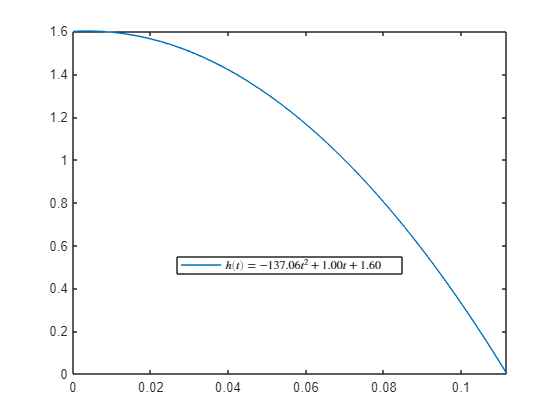

v0 = 1;
h0 = 1.6;
syms t;
[fh, tmax] = solveParabolicMotion(g, v0, h0);

Once you have chosen your planet and set up your trajectory, let's use calculus to study the motion. We have already established that the height of our object is given by $h(t) = -\frac{g}{2}t^2+v_0t+h_0$. The velocity of our object is given by $v(t) = \frac{d}{dt}[h(t)]$. You may use either numbers or the variables g, v0, and h0 to express your result.

v = @(t) -g*t+v0;
checkVelocity(v, fh)

Correct.


Thinking about what you know about derivatives, what is the velocity at the apex of the parabola?

apexVelocity = "zero";
checkApexVelocity(apexVelocity);

Correct!


Can you solve for the point at which the apex of the parabola is achieved? 

Correct.
Note: As a theme in calculus, you can replace some of the specific formulas you memorized
      in the past with general rules from calculus that allow you to quickly compute solutions.


tmax =    0.007295808557983


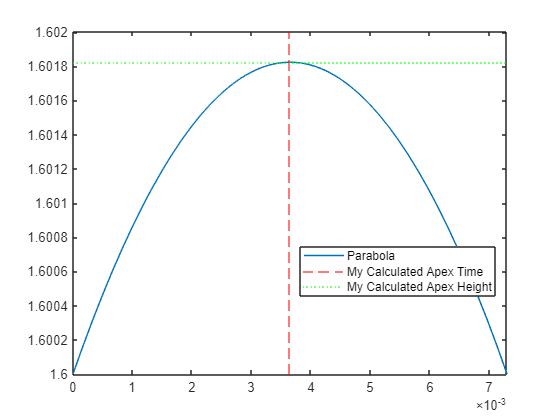

tApex = 1/g;
hApex = fh(tApex);
checkApex(tApex, hApex, g, v0, h0);

## Transcendental Functions

Have you encountered transcendental numbers like $e\approx 2.71828182459046$ or $\pi \approx 3.141592653589793$? They are called *transcendental* because they are not *algebraic,* that is they are not a root of any finite degree polynomial equation with integer coefficients. All rational numbers are algebraic, e.g., $r = \frac{p}{q}$ is a root of $y = qx-p$, but many irrational numbers are algebraic as well, e.g., $r=\sqrt{5}$ is a root of $y=x^2-5$. Notice that you can still approximate transcendental numbers by the sequence of decimal expansions. A *transcendental function* is a function that you can approximate by a sequence of polynomial functions, but that is not the solution to a polynomial equation itself. The most common transendental functions are the exponential, logarithm, and trigonometric functions.

### Trigonometric Functions

Trigonometric functions are the family of functions that relate the ratios of sides to the angles in right triangles. 

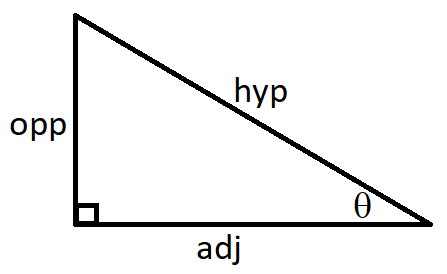

The abbreviations are

 opp = "length of the side opposite the angle $\theta$",                                  

adj = "length of the side between the right angle and the angle $\theta$", 

and 

hyp = "length of the hypotenuse".                                                      

#### Sines

The function $y = \sin(\theta)$ tracks the ratio $\frac{\text{opp}}{\text{hyp}}$. 

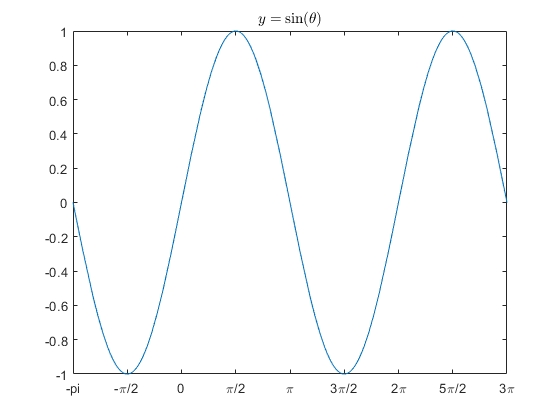

Let's try to determine the derivative $\frac{dy}{d\theta}$ of $y=\sin(\theta)$ by computing its numerical approximation. First, let's pick a step size $h$ to use in the difference quotient: $\frac{dy}{d\theta} \approx \frac{y(\theta+h)-y(\theta)}{h}$.

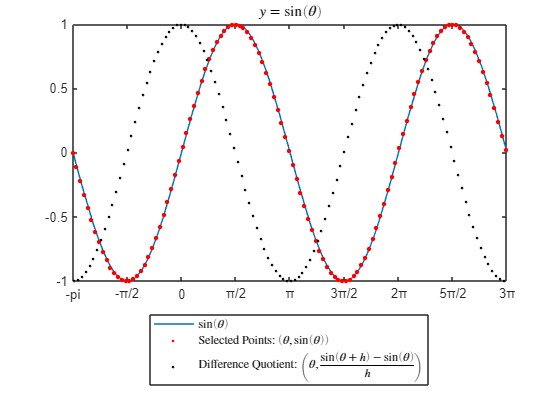

dt = 0.11;
 
graphApproxDer(@(t) sin(t), "sin", dt, [-pi,3*pi])

Do you recognize the approximate derivative? Use the independent variable name t:

syms t
derGuess = @(t,theta)cos(t);
 
checkSinDer(derGuess)

Correct.


#### Cosines

The function $\cos(\theta)$ tracks the ratio $\frac{\text{adj}}{\text{hyp}}$. 

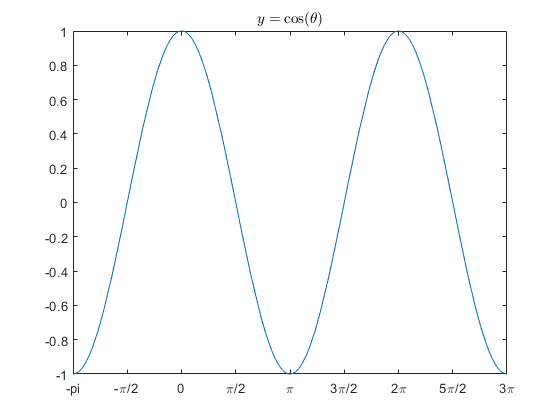

Let's try to determine the derivative $\frac{dy}{d\theta}$ of $y=\cos(\theta)$ by computing its numerical approximation. First, let's pick a step size $h$ to use in the difference quotient: $\frac{dy}{d\theta} \approx \frac{y(\theta+h)-y(\theta)}{h}$.

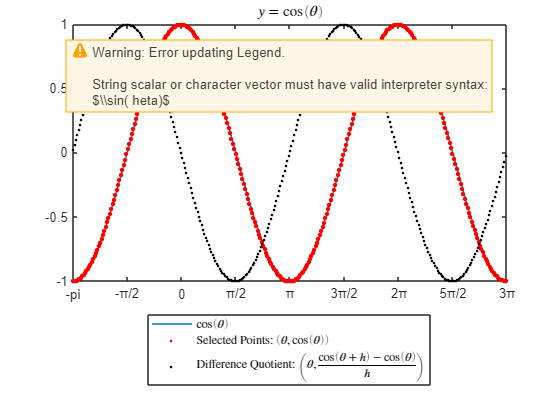

dt = 0.04;
 
graphApproxDer(@(t) cos(t), "cos", dt, [-pi,3*pi])

The derivative of $y=\sin(\theta)$ was $y' = \cos(\theta)$. It appears that the derivative of $y=\cos(\theta)$ is also a sinusoidal function. Use the slider to test values of the phase shift $\phi$ to determine the function $\frac{d}{d\theta}\left[\cos(\theta)\right] = \cos(\theta+\phi)$.

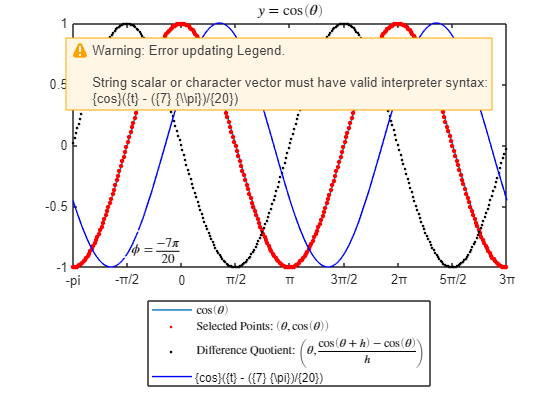

mult = -0.35;
graphApproxDer(@(t) cos(t), "cos", dt, [-pi,3*pi])
graphDerGuess(@(t) cos(t), mult)

Once you have chosen the best possible function to fit the approximate derivative, you can check your result here using t as your independent variable. If you wish, you may also use phi for the value $\phi$ you set above or pi for the value $\pi$ :

phi = mult*pi;
syms(t)
cosDerGuess = @(t)cos(t+.5*pi);
checkCosDer(cosDerGuess)

Correct. It is more common to write -sin(t), however.


#### Second Derivatives

As discussed in [derivativeDefinition.mlx](matlab:open('./derivativeDefinition.mlx')), the derivative is a linear operator. In particular, since the derivative of a function is another function, it is possible to take several derivatives in sequence:

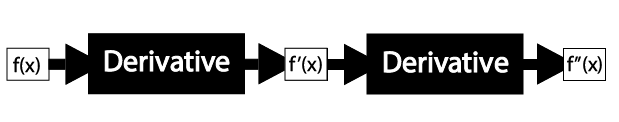

Let's assume the units of $f(x)$ are frogs and the units of $x$ are feet. Then 

$f(x)$ is the number of frogs                                                        

$f'(x)$ is the number of frogs per foot ($\frac{\text{frogs}}{\text{foot}}$)                               

$f^{\prime \prime}(x)$ is the number of frogs per square foot ($\frac{\text{frogs/foot}}{\text{foot}} = \frac{\text{frogs}}{\text{foot}^2}$)

 **Notation**

**Prime Notation**

$f(x)$, $f'(x)$, $f''(x)$, $f'''(x)$, $f^{(iv)}(x)$, $f^{(v)}(x)$, $\ldots$, $f^{(n)}(x)$

**Differential Notation**

$f(x)$,     $\frac{df}{dx}$,     $\frac{d^2f}{dx^2}$,     $\frac{d^3f}{dx^3}$,     $\frac{d^4f}{dx^4}$,     $\frac{d^5f}{dx^5}$,     $\ldots$,     $\frac{d^nf}{dx^n}$

**Operator Notation**

$f(x)$, $\frac{d}{dx}[f]$, $\frac{d}{dx}\left[\frac{d}{dx}[f]\right] = \frac{d^2}{dx^2}[f]$, $\frac{d}{dx}\left[\frac{d}{dx}\left[\frac{d}{dx}[f]\right]\right] = \frac{d^3}{dx^3}[f]$, $\ldots$, $\frac{d^n}{dx^n}[f]$

  **Try**

- If the units of $g(y)$ are

gUnits = "ohms";

and the units of $y$ are

yUnits = "sec";

and $n$ is

n = randi([2 5])

n = 2

If we calculate the $n$th derivative of $g$ with respect to $y$ the units will be:

opts = setOptions(gUnits, yUnits);

Your options are: 
Option 1: ohms/sec
Option 2: ohms/sec^2
Option 3: ohms/sec^3
Option 4: ohms/sec^4
Option 5: ohms/sec^5


dngdyn = 2

dngdyn = 2

checkGYUnits(dngdyn, n);

Correct!


#### Application: Springs

Consider a simple mass-spring system with mass $m$ and stiffness coefficient $k$:

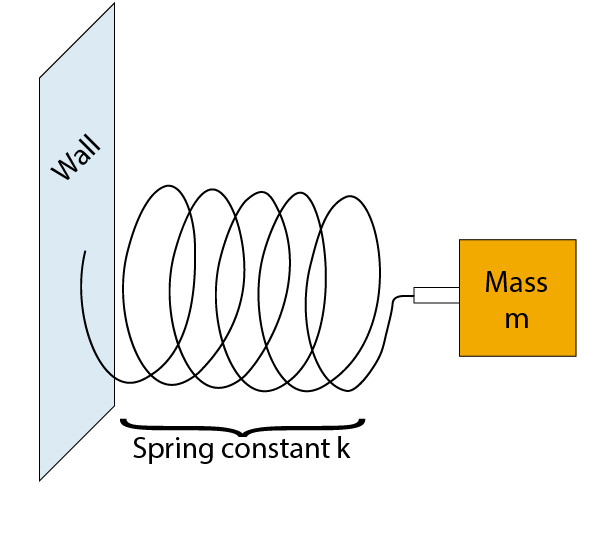

Then the motion of the mass as a function of the horizontal displacement $x = p(t)$ is given by a differential equation (that is an equation involving derivatives): 

                                         
$$\text{Force} = -k\cdot \left(\text{Displacement from Equilibrium}\right)$$



$$\text{Mass} \times \text{Acceleration} = -k\cdot p(t)$$
                            


$$m\cdot \frac{d}{dt}\left[\frac{d}{dt}\left[p(t)\right]\right] = -k\cdot p(t)$$
                      

$\frac{d^2p}{dt^2} = -\frac{k}{m}p(t)$,

where the force generated by the spring is acting in opposition to the displacement from equilibrium.  Thus, if $p(t)>0$, then the acceleration of the mass is in the negative direction towards zero and if $p(t)<0$, then the acceleration of the mass is in the positive direction towards zero. The equilibrium position, where the mass will stay at rest if it starts at rest is $p(t)=0$.

** Exercise**. Let's consider a case where $k=m=1$. Check whether any functions that you know satisfy this differential equation, that is if you calculated $p''(t)$ is that the same value as $p(t)$.

- $p(t) = x^n$ for any constant $n$

- 
$$p(t) = \sin(t)$$


- 
$$p(t) = \cos(t)$$


- 
$$p(t) = 3\sin(t)-7\cos(t)$$


one = false; two = true; three = true; four = true;
checkEqns(one, two, three, four);

Correct!)
 Any linear combination of sines and cosines will be a solution to this differential equation.


### Exponential Functions

#### Application: Population Growth

### Logarithms

## Chain Rule

### Application: Pendulum

## Product Rule

### Application: Lamellophone

### Quotient Rule

sympref(oldPrefs);   % Restore the system preferences you had before running this script.

## Helper Functions

function g = getGravity(planet)
    switch planet
        case "Mercury"
            g = 3.59;
        case "Venus"
            g = 8.87;
        case "Earth"
            g = 9.81;  
        case "Mars" 
            g = 3.71;
        case "Jupiter"
            g = 25.95;
        case "Moon"
            g = 1.62;
        case "Saturn"
            g = 11.08; 
        case "Neptune"
            g = 14.07;
        case "Uranus"
            g = 10.67;
        case "Pluto"
            g = .62;
        case "Sun"
            g = 274.13;
    end
end

function [fh, tmax] = solveParabolicMotion(g, v0, h0)
        syms t
        fh = @(t)-g*t^2/2 + v0*t+h0;
    if v0 < 0 && h0 < 0
        disp("You have to throw upwards, and be above the ground, or the ball won't travel anywhere!")
        disp("Please set positive v0 and h0 values and run this again.")
        tmax = abs(2*v0/g);
    elseif v0 < 0
        disp("We would like to study parabolic motion with an apex.")
        disp("Please set a positive value of v0 and run this again.")
        tmax = abs(2*v0/g);
    end
    if h0 > 0
        tmax = max(roots([-g/2, v0, h0]));
    else
        tmax = 2*v0/g;
    end
    fplot(fh,[0 tmax])
    formatSpec = "$h(t) = %.2ft^2+%.2ft+%.2f$";
    hStr = compose(formatSpec, [-g/2, v0, h0]);
    legend(hStr, "Interpreter","latex", "Location","best")
end

function checkVelocity(v, fh)
    syms t
    f(t) = fh(t);
    df(t) = diff(f, t);
    correctSym = df(t);
    if v == correctSym
        disp("Correct.")
    else
        correctG = double(diff(f, t, 2));
        correctV0 = double(df(0));
        answerG = double(diff(v,t));
        answerV0 = v(0);
        if correctG == answerG
            disp("You made a mistake with the constant term.")
            disp("Please check your work and resubmit.")
        elseif correctV0 == answerV0
            disp("You made a mistake with the linear term.")
            disp("Please check your work and resubmit.")
        else
            disp("Please review the rules for computing derivatives of polynomials.")
            disp("Then fix your answer and resubmit.")
        end
    end
end

function checkApexVelocity(str)
    if str == "zero"
        disp("Correct!")
    else
        disp("That is not correct. Please review what you know about graphical derivatives and try again.")
    end
end

function checkApex(tGuess, hGuess, g, v0, h0)
    syms t
    fh = @(t) -g/2*t^2+v0*t+h0;
    if tGuess == v0/g && hGuess == fh(v0/g)
        disp("Correct.")
        disp("Note: As a theme in calculus, you can replace some of the specific formulas you memorized")
        disp("      in the past with general rules from calculus that allow you to quickly compute solutions.")
    elseif tGuess == v0/g && hGuess ~= fh(v0/g)
        disp("You have the correct time, but the incorrect height.")
        disp("How can you evaluate the height at a given time?")
        disp("Please check your work and resubmit your solutions.")
    elseif tGuess ~= v0/g && hGuess == fh(v0/g)
        disp("You have the correct maximal height, but the incorrect time.")
        disp("Remember that the velocity is zero at the apex. How can you use that to find the time?")
        disp("Please check your work and resubmit your solutions.")
    else
        disp("Your answers are incorrect. Please note that they need to be exact values so it may be easiest to work in terms of g, v0, and h0.")
        disp("Remember that the velocity is zero at the apex. How can you use that to find the time?")
        disp("Once you know the time, how can you find the height at that time?")
        disp("Please check your work and resubmit your solutions.")
    end
    tmax = double(abs(v0/g*2))
    fplot(fh, [0, tmax])
    ax = gca;
    yLimits = ax.YLim;
    yLimits(2) = .1*(yLimits(2)-yLimits(1))+yLimits(2);
    ax.YLim = yLimits;
    hold on
    xline(tGuess, "r--")
    yline(hGuess, "g:")
    legend("Parabola", "My Calculated Apex Time", "My Calculated Apex Height", "Location","best")
    hold off
end

function checkPwrRule(dfdx)
    syms x n
    pwrRule = n*x^(n-1);
    correct = isequal(dfdx, pwrRule);
    if correct
        disp("Good work! The power rule is f'(x) = n*x^(n-1).")
    else
        disp("No, that isn't correct. Please try again.")
    end
end

function checkSinDer(fh)
    syms t
    if cos(t) == fh(t)
        disp("Correct.")
    elseif cos(t) == simplify(fh(t))
        disp("Correct. It is more common to write cos(t), however.")
    else
        disp("Incorrect. What other sinusoidal functions do you know?")
    end
end

function graphApproxDer(fh, fs, dt, bds)
% graphApproxDer plots a function and calculates and plots its numerical
% derivative with step size dt
% 
% fh is a function handle
% fs is the same function name as a string
% dt is the step size
% bds is a 1x2 vector [lower_bound upper_bound]
    syms t
    fplot(fh(t),bds);
    if bds(1) == -pi
        formatTitle = '$y = \\%s(\\theta)$';
        xticks(-pi:pi/2:3*pi)
        xticklabels({'-pi', '-\pi/2', '0', '\pi/2', '\pi', '3\pi/2', '2\pi', '5\pi/2', '3\pi'})
        formatLegend1 = "$\\%s(\\theta)$";
        formatLegend2 = "Difference Quotient: $\\left(\\theta, \\frac{\\%s(\\theta+h)-\\%s(\\theta)}{h}\\right)$";
        formatPts = "Selected Points: $\\left(\\theta, \\%s(\\theta)\\right)$";
    else
        formatTitle = '$y = \\%s(x)$';     
        xticks(linspace(bds(1), bds(2),10))
        xticklabels(linspace(bds(1), bds(2),10))
        formatLegend1 = "$\\%s(x)$";
        formatLegend2 = "Difference Quotient: $\\left(x,\\frac{\\%s(x+h)-\\%s(x)}{h}\\right)$";
        formatPts = "Selected Points: $\\left(x,\\%s(x)\\right)$";
    end
    graphTitle = compose(formatTitle, fs);
    line1 = compose(formatLegend1, fs);
    line2 = compose(formatLegend2, fs, fs);
    pts = compose(formatPts, fs);
    title(graphTitle,'Interpreter', 'latex')
    tVals = bds(1):dt:bds(2);
    yVals = fh(tVals);
    hold on
    scatter(tVals,yVals, 100, "r.")
    hold off
 
    derVals = (yVals(2:end)-yVals(1:end-1))/dt; % Numerical derivative
    mdPts = (tVals(2:end)+tVals(1:end-1))/2;    % Interval midpoints for graphing
    hold on
    plot(mdPts, derVals, "k.")
    legend(line1, pts, line2, ...
    "Interpreter", "latex", "Location","southoutside")
    hold off
end

function graphDerGuess(fh, mult)
    syms t
    hold on
    fplot(fh(t+mult*pi), [-pi, 3*pi], "b-")
    dim = [.22 .25 .2 .2];
    [num, den] = rat(abs(mult));
    if mult < 0
        num = -num;
    end
    if den ~= 1 && num ~= 1
        formatStr = "$\\phi = \\frac{%d\\pi}{%u}$";
        str = compose(formatStr, num, den);
    elseif den ~= 1 && num == 1
        formatStr = "$\\phi = \\frac{\\pi}{%u}$";
        str = compose(formatStr, den);    
    elseif num == 1 && den == 1
        formatStr = "$\\phi = \\pi$";
    elseif num == -1 && den == 1
        formatStr = "$\\phi = -\\pi$";
    else
        formatStr = "$\\phi = %d\\pi$";
        str = compose(formatStr, num);
    end
    annotation("textbox", dim, "String", str, "FitBoxToText","on", "Interpreter","latex", "EdgeColor",[1 1 1])
    hold off
end

function checkCosDer(fh)
    syms t
    if -sin(t) == fh(t)
        disp("Correct.")
    elseif -sin(t) == simplify(fh(t))
        disp("Correct. It is more common to write -sin(t), however.")
    else
        disp("Incorrect. Try to find a better fit.")
    end
end

function gyOpts = setOptions(gUnits, yUnits)
    formatgy = "%s/%s";
    formatgy2 = "%s/%s^2";
    formatgy3 = "%s/%s^3";
    formatgy4 = "%s/%s^4";
    formatgy5 = "%s/%s^5";
    gyOpts = compose([formatgy, formatgy2, formatgy3, formatgy4, formatgy5], gUnits, yUnits);
    disp("Your options are: ")
    disp("Option 1: " + gyOpts(1))
    disp("Option 2: " + gyOpts(2))
    disp("Option 3: " + gyOpts(3))
    disp("Option 4: " + gyOpts(4)) 
    disp("Option 5: " + gyOpts(5)) 
end

function checkGYUnits(myAnswer, n)
    if myAnswer == n
        disp("Correct!")
    else
        disp("Remember that every derivative involves dividing by the units of the independent variable.")
        disp("Please try again.")
    end
end

function checkEqns(a, b, c, d)
    if ~a && b && c && d
        disp("Correct!")
        disp(" Any linear combination of sines and cosines will be a solution to this differential equation.")
    else
        disp("Please check your derivatives.")
        disp("One of these functions does not work and three of them do.")
        disp("Why?")
    end
end


function [myFun, varChoice] = genProb(varOpts, probType)
varChoice = varOpts(randi([1 length(varOpts)], 1));
a = 0; 
b = 0;
switch probType
    case "power" % Simple derivative
        myFun = genFunDiff(varChoice, 1, 10, "power");
        disp("Take the derivative with respect to: ")
        disp(varChoice) 
        disp(" of the function f = ") 
        disp(myFun)
    case "exponential" % Simple derivative
        myFun = genFunDiff(varChoice, 1, 10, "exponential");
        disp("Take the derivative with respect to: ")
        disp(varChoice) 
        disp(" of the function f = ") 
        disp(myFun)
    case "ln" % Simple derivative
        myFun = genFunDiff(varChoice, 1, 10, "ln");
        disp("Take the derivative with respect to: ")
        disp(varChoice) 
        disp(" of the function f = ") 
        disp(myFun)     
    case "sinusoid" % Simple derivative
        myFun = genFunDiff(varChoice, 1, 10, "sinusoid");
        disp("Take the derivative with respect to: ")
        disp(varChoice) 
        disp(" of the function f = ") 
        disp(myFun)  
    case "product" % Product rule derivative
        syms f(x) g(x)
        f(x) = genFunDiff(x, 1, 7, "product");
        g(x) = genFunDiff(x, 1, 7, "product");
        myFun = f(varChoice)*g(varChoice);
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function f = ")
        disp(myFun)
    case "chain" % Chain rule derivative
        syms f(x) g(x)
        f(x) = genFunDiff(x, 1, 3, "chain");
        g(x) = genFunDiff(x, 1, 5, "chain");
        myFun = f(g(varChoice));
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function f = ")
        disp(myFun)
end
end

Generate a random function with a simple derivative:

function myFun = genFunDiff(var,lower,upper, fType)
syms f(t) 
params = randi([lower upper],[1,5]);
sgn1 = randi([0 1], 1);
sgn2 = randi([0 1], 1);
sgn3 = randi([0 1], 1);
if fType == "power"
    type = randi([1 4], 1);
elseif fType == "exponential"
    type = 5;
elseif fType == "ln"
    type = 6;
elseif fType == "sinusoid"
    type = randi([7 8], 1);
else
    type = randi([1 8], 1);
end
a = (-1)^sgn1*params(1);
b = (-1)^sgn2*params(2);
c = max(params(3),params(5)); 
d = (-1)^sgn3*params(4);
e = params(3);

switch type
    case 1
        f(t) = a*t^(b);
    case 2
        f(t) = a*t^(b/c);
    case 3
        f(t) = a*t^(b)+c*t^(d);
    case 4
        f(t) = a*t^(b/c)+d*t^(e);
    case 5
        f(t) = a*exp(b*t);
        disp("Remember that exp(x) is the notation for e^x in MATLAB.")
    case 6
        f(t) = a*log(abs(b)*t);
        disp("Remember that log(x) is the notation for a natural logarithm in MATLAB.")
    case 7
        f(t) = a*sin(b*t+d);
    case 8
        f(t) = a*cos(b*t+d);
end

myFun = f(var);
end

Generate correct answers:

function correctAnswer = check(myFunc, myVar, myAnswer)

    correctAnswer = diff(myFunc,myVar);
    disp("When simplified, my answer is: ")
    myAnswer
    if correctAnswer == myAnswer
        disp("My answer is correct.")
    else
        disp("My answer is incorrect. The correct answer is:");
        correctAnswer
        disp("Please try again with a new problem.")
    end
end
